% Calculate thermal resistances

R_cond = @(L,k,A) L/(k*A);
R_conv = @(h,A) 1/(h*A);

h_ins = 15; % heat transfer coefficient of indoor surfaces in W/m2*K
h_out = 30; % heat transfer coefficient of outdoor surfaces in W/m2*K

A_abs = 5*5.1; % surface area of absorber in m2 
L_abs = 0.05; % thickness of absorber in m

A_wind = 5*2.6; % surface area of window in m2 
h_wind = 0.7; % heat transfer coefficient of window in W/m2*K

A_wall = 5*(0.2+5.1+3+5.1+0.4); % surface area of inside walls in m2
k_wall = 0.04; % conductivity of walls in W/m*K
L_wall = 0.05; % thickness of walls in m

R_conv_abs = R_conv(h_ins,A_abs); % thermal resistance for heat convecting from absorber to inside air

R_1 = R_conv_abs 

R_1 = 0.0026


R_conv_wind_ins = R_conv(h_ins,A_wind); % thermal resistance for heat convecting from inside air to window
R_conv_wind = R_conv(h_wind,A_wind); % thermal resistance for heat convecting through window 
R_conv_wind_out = R_conv(h_out,A_wind); % thermal resistance for heat convecting from window to outside air
R_wind = R_conv_wind_ins+R_conv_wind+R_conv_wind_out

R_wind = 0.1176


R_conv_wall_ins = R_conv(h_ins,A_wall); % thermal resistance for heat convecting from inside air to walls
R_cond_wall = R_cond(L_wall,k_wall,A_wall); % thermal resistance for heat conducting through walls
R_conv_wall_out = R_conv(h_out,A_wall); % thermal resistance for heat convecting from walls to outside air
R_wall = R_conv_wall_ins+R_cond_wall+R_conv_wall_out

R_wall = 0.0196


R_2 = 1/(1/R_wind+1/R_wall)

R_2 = 0.0168

d_ins = 1.2754; % density of inside air in kg/m3
v_ins = 5*5.1*3; % volume of inside air in m3
m_ins = d_ins*v_ins; % mass of inside air in kg
c_ins = 1003.5; % specific heat of inside air in J/kg*K
C_ins = m_ins*c_ins; % heat capacity of inside air in J/K

d_abs = 3000; % density of absorber in kg/m3
v_abs = 5*5.1*L_abs; % volume of absorber in m3
m_abs = d_abs*v_abs % mass of absorber in kg

m_abs = 3.8250e+03

c_abs = 800; % specific heat of absorber in J/kg*K
C_abs = m_abs*c_abs; % heat capacity of absorber in J/K

% T_out = -3; % outside temperature in Celsius
T_out = @(t) -3+6*sin((2*pi*t)/(24*60*60)+3*pi/4)

T_out = function_handle with value:
    @(t)-3+6*sin((2*pi*t)/(24*60*60)+3*pi/4)



Q_sun = @(t) (-361*cos(pi*t/(12*3600))+224*cos(pi*t/(6*3600))+210)*A_wind;

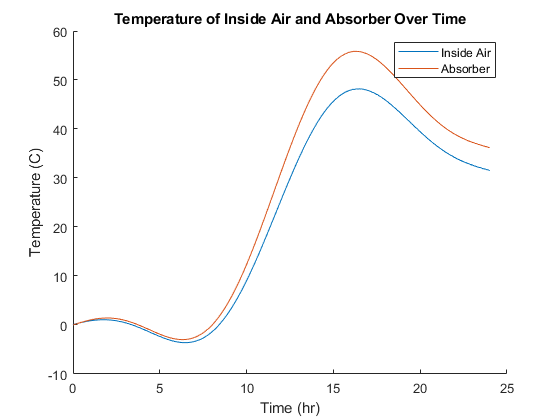

f = @(t,T) [(1/C_ins)*((T(2)-T(1))/R_1-(T(1)-T_out(t))/R_2); (1/C_abs)*(Q_sun(t)-(T(2)-T_out(t))/(R_1+R_2))];

[t,T] = ode45(f,[0 86400],[0 0]);

figure;
hold on
plot(t/3600,T(:,1));
plot(t/3600,T(:,2));
legend('Inside Air', 'Absorber');
title('Temperature of Inside Air and Absorber Over Time')
xlabel('Time (hr)')
ylabel('Temperature (C)')
hold off